clc, clear, close all
run('vlp_testbed_def.m');

VLP definitions and parameters loaded successfully


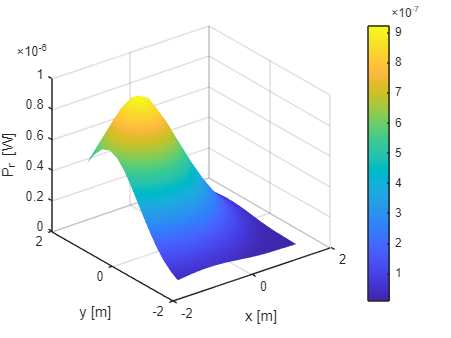


% ===============================================
% Create data based on the lambertian assumtion
% ===============================================

gridstep = 0.25;   % paso del grid [m]
Nsamples = 1000;     % muestras por posición y por AP
rng(1);            % semilla reproducible
channel.sigma2 = 0; % 30e6*10^(-23.0); %0
min_Pr = 1e-12 ; % evitar potencias negativas

% Ground truth positions
xv = testbed.x(1):gridstep:testbed.x(2);
yv = testbed.y(1):gridstep:testbed.y(2);
[X, Y] = meshgrid(xv, yv);
Z      = UE.pos(3);  % altura fija del UE
Npos = numel(X);
nAP  = numel(AP);
P_r = cell(Npos, nAP);

for i_pos = 1:Npos
    UE.pos(1:2) = [X(i_pos), Y(i_pos)];
    for i = 1:nAP
        h0 = h_LOS(AP(i), UE, 'datasheet');
        P_r0 = AP(i).P_t * h0; % without noise
        noise  = sqrt(channel.sigma2) * randn(1, Nsamples);
        Pr_samples = P_r0 + noise;
        Pr_samples = max(Pr_samples, min_Pr);
        P_r{i_pos, i} = Pr_samples;
    end
end

figure(1)
Pr_mean_AP1 = cellfun(@(x) mean(x), P_r(:,1));
surf(X, Y, reshape(Pr_mean_AP1, size(X)));
xlabel('x [m]'); ylabel('y [m]'); zlabel('P_r [W]');
shading interp; colorbar;

**Para ambos metodos se requiere la media**

P_r_mean = zeros(Npos, nAP);
for i=1:nAP
    P_r_mean(:, i) = cellfun(@(x) mean(x), P_r(:,i));
end


**Estimación por trilaterizacion**

est_pos = zeros(Npos, 2);   % (x_est, y_est)
true_pos = [X(:), Y(:)];
d_est_all = zeros(Npos, nAP);

for ip = 1:Npos
    % Medición media para esta posición (nAP x 1)
    Pr_i = P_r_mean(ip, :).';
    
    % --- Estimar distancia por inversa del modelo LOS ---
    d_i = zeros(nAP,1);
    for i = 1:nAP
        h_vert = AP(i).pos(3)-UE.pos(3);
        d_i(i) = ( ((AP(i).m+1)/(2*pi)) * UE.A_det*...
                      UE.Ts * UE.g_ri * (h_vert^(AP(i).m+1))*...
                       (AP(i).P_t)/Pr_i(i)) ^ (1/(AP(i).m+3));
    end
    d_est_all(ip,:) = d_i;

    % --- Resuelve posición (x,y) por mínimos cuadrados ---
    % Ecuaciones: (x - xi)^2 + (y - yi)^2 = di^2
    A = []; b = [];
    ref = 1;  % toma AP1 como referencia
    x1 = AP(ref).pos(1); y1 = AP(ref).pos(2);
    for ia = 2:nAP
        xi = AP(ia).pos(1); yi = AP(ia).pos(2);
        A = [A; 2*(xi - x1), 2*(yi - y1)];
        r1 = sqrt(d_i(ref)^2 - h_vert^2);
        ri = sqrt(d_i(ia)^2  - h_vert^2);
        b = [b; (r1^2 - ri^2) + (xi^2 + yi^2) - (x1^2 + y1^2) ];
    end
    
    if rank(A) == 2
        pos_est = A\b;
        %est_pos(ip,:) = pos_est';
        est_pos(ip,:)= inv(A'*A)*A'*b;
    else
        est_pos(ip,:) = [NaN, NaN];
    end
end

Grafica

err = sqrt(sum((est_pos - true_pos).^2,2));
RMSE = sqrt(mean(err.^2));
fprintf('RMSE de estimación: %.3f cm\n', RMSE*100);

RMSE de estimación: 43.260 cm


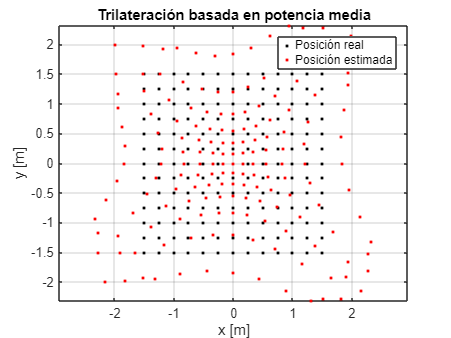


figure;
plot(true_pos(:,1), true_pos(:,2), '.k'); hold on;
plot(est_pos(:,1), est_pos(:,2), 'r.');
legend('Posición real','Posición estimada');
title('Trilateración basada en potencia media');
xlabel('x [m]'); ylabel('y [m]'); axis equal; grid on;